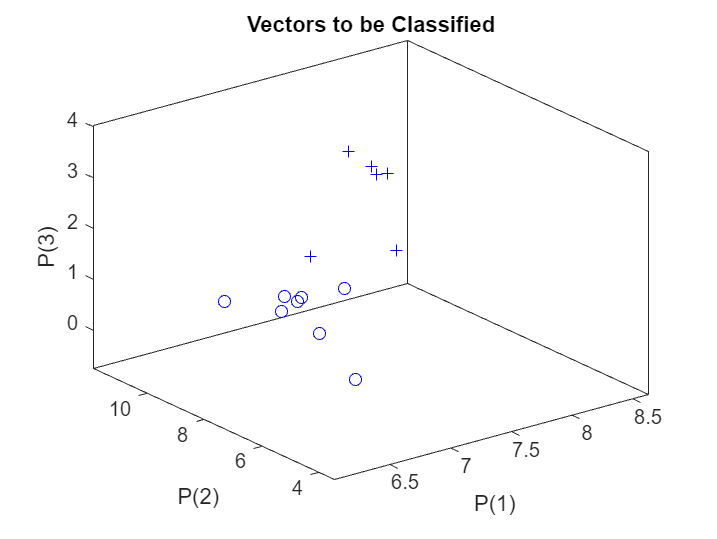

%国家类型的自适应分类(变量数值统一到0.1到10之间)
clear                                       %清理内存
P=[79.1	76.8 80.0 78.7 73.1 75.0 75.8 66.7 71.3	70.7 72.9 69.8 69.4 66.7
99.0 99.0 99.0 99.0 96.7 74.6 96.4 99.5	98.2 91.2 99.0 92.8 77.8 53.7
23582 29605 23257 25512	12013 17719	3967 6460 4809 6006 3353 4288 4036 3041]; 
s=[10 10 10000]';                           %设计一个变量规范化向量
S=s(:,ones(length(P),1));                   %规范化向量平移为矩阵
P=P./S;                                     %变量除以规范化数值
T=[1 1 1 1 1 1 0 0 0 0 0 0 0 0];            %目标输出
plotpv(P,T);                                %绘制感知器的输入向量和目标向量
net=newp(minmax(P),1);                      %创建一个感知器网络
handle=plotpc(net.iw{1},net.b{1});          %在训练前的分类图中绘制分界面
net.adaptParam.passes=2;                    %设定自适应循环次数为2次
handle=plotpc(net.iw{1},net.b{1});
for a=1:15                                  %指定迭代次数为15次
    [net,Y,e]=adapt(net,P,T);               %调用自适应函数训练网络
    handle=plotpc(net.iw{1},net.b{1},handle);
    drawnow;                                %添加分类界面
end;

Y                                           %输出结果

Y =      1     1     1     1     1     1     1     1     1     1     1     1     1     1


Q=[78.7 78.2 70.2 68.0
99.0 96.9 97.9 82.8
20659 13943	5648 3105];                     %输入待判样品信号
P_test=Q./s(:,ones(length(Q),1));           %待判样品信号的规范化
y=sim(net,P_test);y                         %待判样品的仿真结果

y =      0     0     0     0
